# PARTE 2: Laboratorio 1 MyS

Se busca graficar la respuesta de un sistema indicado en un diagrama de bloque frente al escalón unitario.

Definición de constantes para los valores de las funciones de transferencia indicadas en el diagrama del enunciado.

% Se limpian las variables guardadas en el Workspace
clearvars;
% Se define el modelo para las funciones de transferencia
s = tf('s');

% Definición de constantes
F_1 = 4*s/(10*s^2+4)

F_1 =
 
     4 s
  ----------
  10 s^2 + 4
 
Continuous-time transfer function.



F_2 = 3/(6*s+16)

F_2 =
 
     3
  --------
  6 s + 16
 
Continuous-time transfer function.



F_3 = (4*s + 10)/(4*s^3+9*s^2+5*s)

F_3 =
 
       4 s + 10
  -------------------
  4 s^3 + 9 s^2 + 5 s
 
Continuous-time transfer function.



F_4 = 1/(7*s+10)

F_4 =
 
     1
  --------
  7 s + 10
 
Continuous-time transfer function.



F_5 = (8*s+8)/(s^3+2*s^2+3*s)

F_5 =
 
       8 s + 8
  -----------------
  s^3 + 2 s^2 + 3 s
 
Continuous-time transfer function.



F_6 = (3*s+2)/(5*s^2+7*s+10)

F_6 =
 
      3 s + 2
  ----------------
  5 s^2 + 7 s + 10
 
Continuous-time transfer function.



Luego, se debe analizar el diagrama de bloque para encontrar la función de transferencia. Se empieza por el tercer parámetro del sumador para la salida, dado que se conocen los valores de las dos primeras funciones de transferencia.

% La función 3 recibe una retroalimentación positiva
H_3 = feedback(F_3,1);

% Función 4 y función 5 poseen una conexión en serie, cuya entrada es la
% retroalimentación de la función 3
H_4 = H_3 * F_4;
H_5 = H_3 * F_5;

% La función 6 posee una conexión en paralelo, cuyas entradas son la
% función 4 y 5.
H_6 = (H_4 + H_5) * F_6;

Dado que conocemos el tercer parámetro del sumador, se completa la conexión en paralelo de todo el sistema.

H = F_1 + F_2 + H_6

H =
 
                                                                                                                                                                    
  30240 s^14 + 317936 s^13 + 1.67e06 s^12 + 5.802e06 s^11 + 1.495e07 s^10 + 3.082e07 s^9 + 5.313e07 s^8 + 7.666e07 s^7 + 9.098e07 s^6 + 8.766e07 s^5 + 6.685e07 s^4 
                                                                                                                                                                    
                                                                                                                + 3.861e07 s^3 + 1.663e07 s^2 + 5.39e06 s + 1.024e06
                                                                                                                                                                    
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------
   

Finalmente, se grafica la respuesta del sistema frente al escalón unitario.

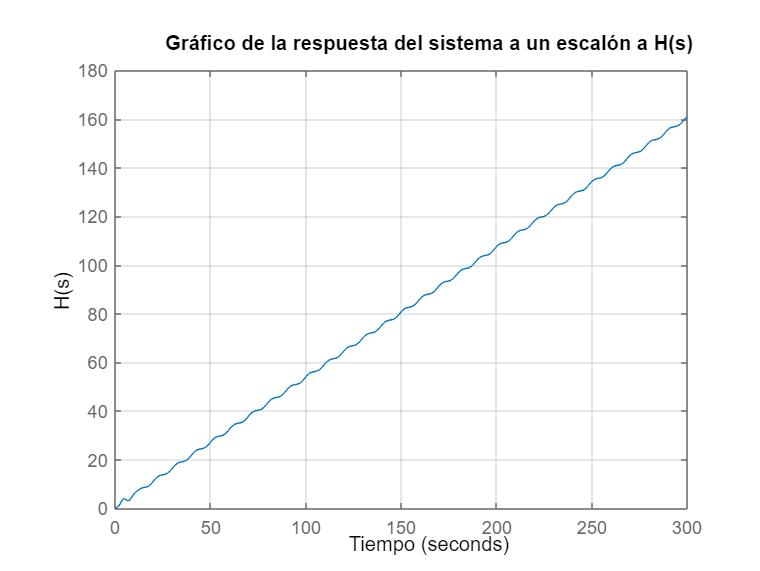

% Gráfico para la respuesta del sistema a un escalón
figure;
step(H);
title("Gráfico de la respuesta del sistema a un escalón a H(s)")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");